# **DNP3 - Loopback**

DNP3 is an Ethernet communication protocol based on a client-server architecture. Servers define so-called points of different types (binary, counter, analog) that clients can read and write on request. Servers can also send unsolicited messages when the values of specific points change. This example demonstrates the communication between one DNP3 client and one DNP3 server. 

Both DNP3 stations are in the same system and on the same Ethernet interface. This is achieved by assigning multiple IP addresses to one Ethernet interface. 

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with at least one unused Ethernet interface

- "Runtime License File" that includes one DNP3 client license and one DNP3 server license. Refer to the [Runtime Licensing](https://www.speedgoat.com/help/slrt/page/io_main/refentry_runtime_license) documentation for more information

### Wiring of Target Machine

No physical wiring is required.

### Ethernet Configuration of the Client and Servers

Use the **Speedgoat Ethernet Configuration Tool** to assign the IP address to one unused Ethernet interface (onboard or IO71x/IO79x) on the target machine. The communication between the client and the server on the unused Ethernet interface is performed over the localhost. No cable is required.

The IP address assigned should be 192.168.10.1; the netmask for this local address is 255.255.255.0. This IP is used as the gateway address for the client and server in this example.

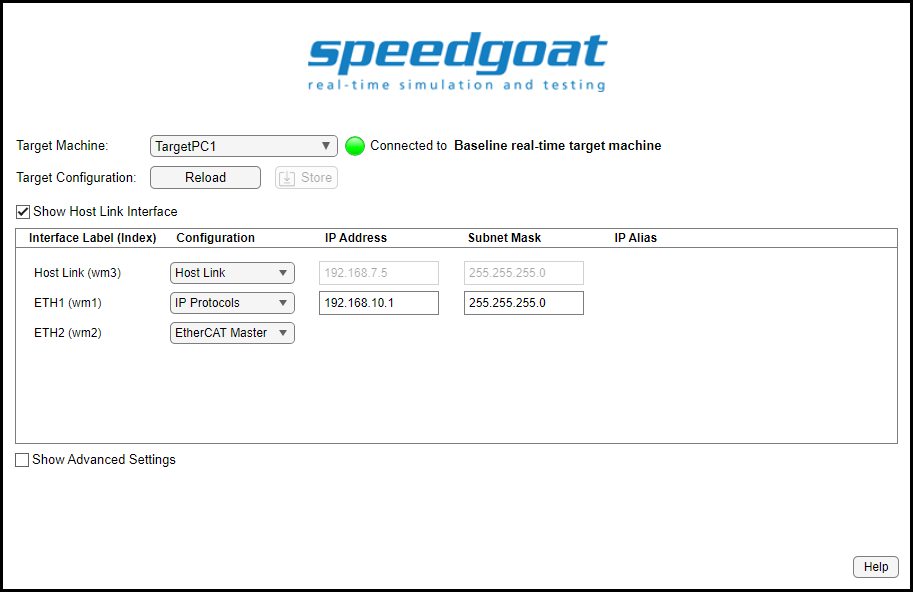

 
% Configure the Ethernet interface for the OPC UA example
speedgoat.configureEthernet; % Open the Speedgoat Ethernet Configuration tool

Add the IP addresses of the client and the server to the same Ethernet interface. Adapt the name of the interface according to your target machine configuration.

 
IP_Client = '192.168.10.100';
IP_Server = '192.168.10.101';

InterfaceName = 'ETH1'; % Ethernet Interface on the target machine used for this example. Adapt this according to your machine.
ipAliasObj = speedgoat.IpAliasConfiguration();
ipAliasObj.add(InterfaceName, {IP_Client, IP_Server});

Check the server Ethernet settings:

ipAliasObj.show();

## Initialize and Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_DNP3_1Client_1Server';
open_system(modelName);

### Model Description

The model sets up the communication for the DNP3 client and the DNP3 server. The client has Station ID 0 and its IP address ends with 100. The server has Station ID 1 and its IP address ends with 101. The Station ID parameter is not related to the DNP3 protocol; instead, it just serves to link blocks in the Simulink model.

Four signal paths are implemented in the Simulink model:

- **Counter Input**: The server defines one counter input point that is updated every millisecond. The client sends read requests every 10 milliseconds and outputs the value received.

- **Analog Input**: The server defines two analog input points that are updated every millisecond. The first signal is a sine wave with an amplitude of 10 and a period of 2 seconds; the second one is a pulse with an amplitude of 2. The client does not explicitly send requests to read the points but prompts the server to send point values autonomously. For that purpose, in the DNP3 Class block, the points are added to class 3 for which the unsolicited transmission is activated. The corresponding DNP3 Client Read block outputs the received data even though the Enable input port is grounded. The server generates an event for each signal change exceeding the analog deadband defined in the DNP3 Server Setup block. On each event, the server sends a message with the new point value to the client, indicating a signal change. When you increase the deadband from 1.5 to 2.1 in the Setup block, you slightly change the form of the sine wave received and cause the server to not generate events for the pulse signal.

- **Analog Output**: The server defines one analog output point, which is written by the client every 10 milliseconds. The signal is a sine wave with an amplitude of 10 and a period of 2 seconds. The corresponding Server Point block outputs the signal.

- **Binary Output**: The server defines one binary output point that the client controls. The client does not just write the point's value; instead, it sends control messages that tell the server how long and how often the point should be set to 1. In this example, the client sends control messages every 2 seconds prompting the server to immediately set the point to a value of 1 and back to 0 after 300 milliseconds. The server generates an event whenever the point value toggles. No unsolicited messaging is activated for the point, but the client periodically sends requests to check if the binary output really changed. In addition to the current value, the corresponding Client Command block outputs the time the server changed the value. The example illustrates how the POSIX™-encoded timestamp is converted into a human-readable time.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download the real-time application to the target machine
tg.load(modelName);

% Set the stop time
tg.setStopTime(10);     % seconds

% Prepare the Simulink Data Inspector to plot signals
Simulink.sdi.clearAllSubPlots;
Simulink.sdi.setSubPlotLayout(2,2);
Simulink.sdi.view;

% Start the real-time application
tg.start;

% Select the signals for plotting, set the axis limits and line colors
sdiRunIDs = Simulink.sdi.getAllRunIDs;
sdiLatestRun = Simulink.sdi.Run.getLatest;
s = sdiLatestRun.getSignalsByName('ReadAnalogInput_Sine');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('ReadAnalogInput_Pulse');
plotOnSubPlot(s,1,1,true);
s = sdiLatestRun.getSignalsByName('ReadBinaryCounter');
plotOnSubPlot(s,1,2,true);
s = sdiLatestRun.getSignalsByName('ReadBinaryOutputControlEvent');
plotOnSubPlot(s,2,1,true);
s = sdiLatestRun.getSignalsByName('AnalogOutputControl');
plotOnSubPlot(s,2,2,true);

Simulink.sdi.setSubplotLimits(1,1,'AllRange',[0,10,-11,11]);
Simulink.sdi.setSubplotLimits(1,2,'AllRange',[0,10,-0,10000]);
Simulink.sdi.setSubplotLimits(2,1,'AllRange',[0,10,-1,2]);
Simulink.sdi.setSubplotLimits(2,2,'AllRange',[0,10,-11,11]);

The output is then visible in the Simulink Data Inspector (SDI). You should see the signals described above.

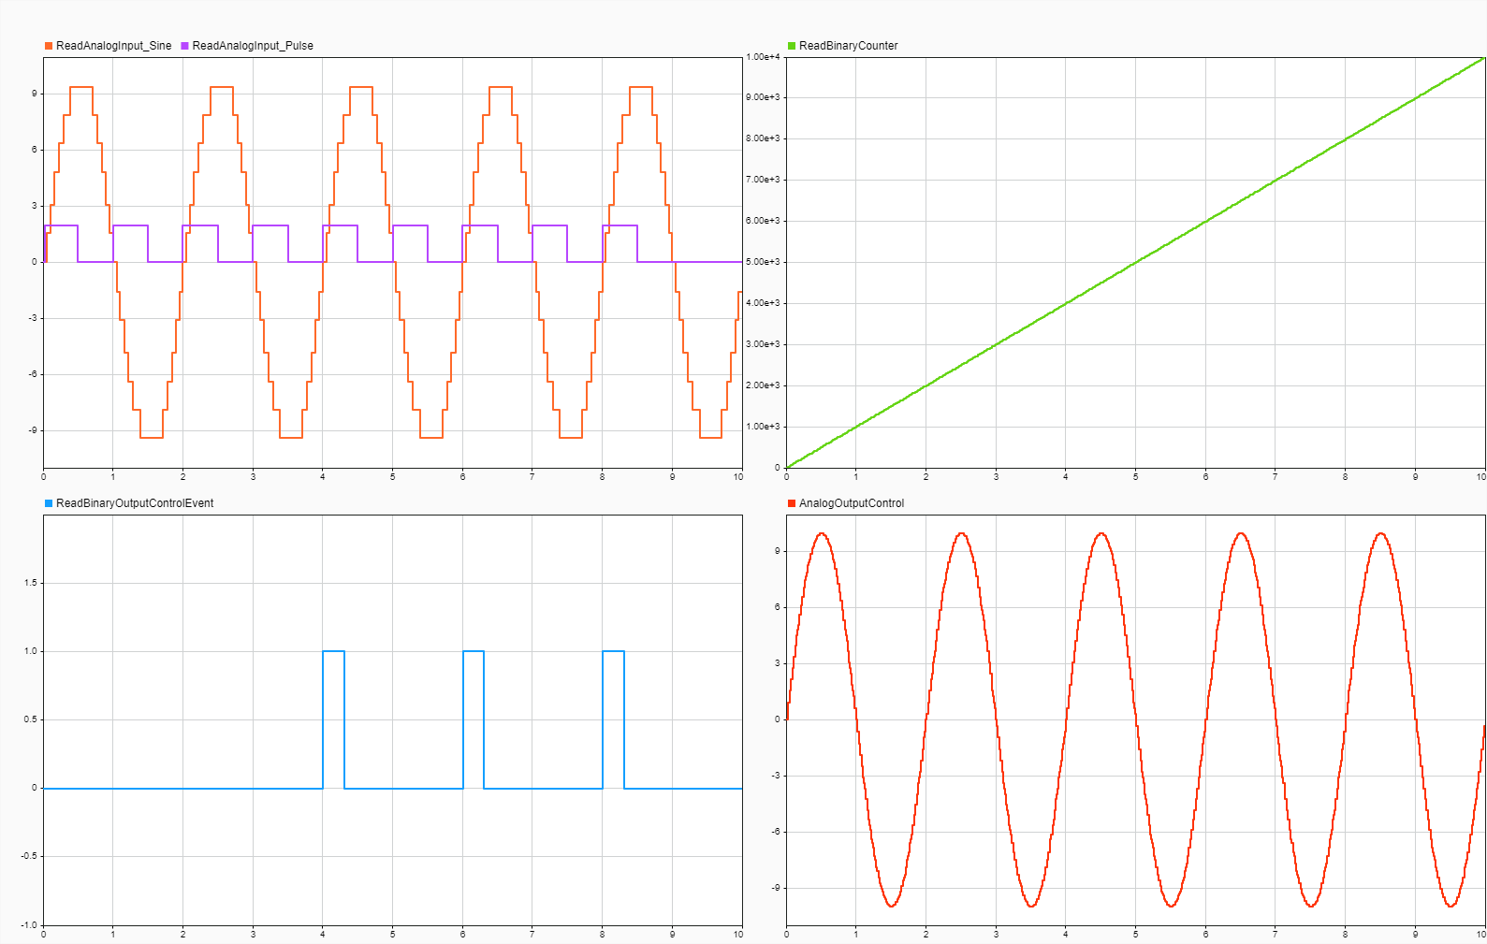

## Restore Target Machine Configuration

To restore the default configuration, simply reopen the **Speedgoat Ethernet Configuration Tool** and tick the **Show Advanced Settings** checkbox. Then click the **Restore** button in the bottom right.

This will erase the IPs of every Ethernet interface and set the host link IP to 192.168.7.5 and the netmask to 255.255.255.0.

We recommend restoring the default settings to reduce possible configuration errors.

## Additional References

- [](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_mbtcp_client)[DNP3 Client documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_dnp3_client)

- [](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_mbtcp_server)[DNP3 Server documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_dnp3_server)